# Condition analysis processing

### Analyze the whisking and seperate the neuronal data into the experimntal conditions

**Load ephys exp**

clear 
clc
close all

experiment = loadExp

experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB108_986'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [811×2 double]
                   PSTHs: []
                   sound: [1×1 struct]
                 running: [3.6654e-04 3.6699e-04 3.6739e-04 3.6775e-04 3.6806e-04 3.6833e-04 3.6855e-04 3.6873e-04 3.6886e-04 3.6896e-04 3.6900e-04 3.6900e-04 3.6896e-04 3.6888e-04 3.6875e-04 3.6857e-04 3.6836e-04 3.6810e-04 3.6780e-04 3.6745e-04 … ]
            evokedEvents: [1×1 struct]
         conditionVector: [1×1 struct]
             

Preprocess the whisking data

% extract whisking data to a variable
whisking = experiment.Whisking.Raw

whisking = 902555×1 single column vector
    1.8744
    1.8744
    1.7351
    1.7351
    0.5930
    2.4611
    1.6733
    2.6305
    2.2434
   -0.2245


% Build band pass filter
Fs = 400; % sf of video 400 frames per second
[b,a] = butter(5,[0.1,100]/200,'bandpass');
whisking_filtered = filtfilt(b,a,double(whisking));

% envelope whisking data
[whisk_envlope,~] = envelope(whisking_filtered);

% smooth whisking data
sigma = 0.2 * Fs; % 200ms kernel
smoothedEnv = imgaussfilt(whisk_envlope, sigma);


% optional plots
figure; plot(whisking) % filtered data
figure; plot(whisking_filtered) % filtered data
figure; plot(whisk_envlope) % envelope
figure; plot(smoothedEnv) % smoothed data

Identify Whisking events

% detrmine threshold 
thershold = 0.8*std(smoothedEnv)


% get times above threshold
whiskingBinary = smoothedEnv > thershold;
cc = bwconncomp(whiskingBinary); % seperate events to continuous ones

% find the whisking epochs and classifay them according to duration
epochs = zeros(cc.NumObjects, 3); % structure: [start, end, type]
minumumDuration = 0.5; % deterine the minumum amountfor epoch
longEpoch = 5; % determine the cut off between long and short epochs

for i = 1:cc.NumObjects
    epochs(i, 1) = cc.PixelIdxList{i}(1);   % start
    epochs(i, 2) = cc.PixelIdxList{i}(end); % end
    duration = (epochs(i, 2) - epochs(i, 1)) / Fs;
    
    if duration > 0.5 && duration <= 5
        epochs(i, 3) = 1; % Short epoch
    elseif duration > 5
        epochs(i, 3) = 2; % Long epoch
    end
end

visualize epochs

figure;
plot(smoothedEnv, 'b'); % Original signal
hold on;
maxY = 3000;
for i = 1:size(epochs, 1)
    startX = epochs(i, 1);
    endX = epochs(i, 2);
    
    if epochs(i, 3) == 1
        fill([startX, endX, endX, startX], [0, 0, maxY, maxY], 'r', 'FaceAlpha', 0.3, 'EdgeColor', 'none');
    elseif epochs(i, 3) == 2
        fill([startX, endX, endX, startX], [0, 0, maxY, maxY], 'g', 'FaceAlpha', 0.3, 'EdgeColor', 'none');
    end
end

hold off;
xlabel('Sample Index');
ylabel('Amplitude');
title('Detected Whisking Epochs');

if epochs(end,2) > length(experiment.Cams.whisking.csv_aligned_frames)
    epochs(end,2) = length(experiment.Cams.whisking.csv_aligned_frames)
end

% align the whisking time wpochs with the ephys samples
epochsEphys = [experiment.Cams.whisking.csv_aligned_frames(epochs(1:end,1:2)),epochs(1:end,3)];

% add the epochs to the experiment data 
experiment.Whisking.smoothed = smoothedEnv;
experiment.Whisking.all = epochsEphys;
experiment.Whisking.short = epochsEphys(epochsEphys(:,3)==1,1:2)
experiment.Whisking.long = epochsEphys(epochsEphys(:,3)==2,1:2)

% Divide whisking epochs to the conditions and dvide the units data to the
% conditions
experiment.conditionVector = experiment.getConVector()

experiment.Units.perCondition = experiment.unitTimesCondition()

experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB109_904'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [5105×2 double]
                   PSTHs: []
                   sound: [1×1 struct]
                 running: [1.7970e-04 1.7864e-04 1.7755e-04 1.7642e-04 1.7526e-04 1.7407e-04 1.7285e-04 1.7160e-04 1.7033e-04 1.6903e-04 1.6771e-04 1.6637e-04 1.6501e-04 1.6363e-04 1.6224e-04 1.6083e-04 1.5941e-04 1.5799e-04 1.5656e-04 1.5513e-04 … ]
            evokedEvents: [1×1 struct]
         conditionVector: [1×1 struct]
            

Visulaize all experimntal conditions

colorPallete
figure;
plot(experiment.Cams.whisking.csv_aligned_frames,experiment.Whisking.smoothed(1:length(experiment.Cams.whisking.csv_aligned_frames)), 'b'); % Original signal
hold on;
maxY = 200;
plot((experiment.sound.smoothed/50)+100)
most_events = max([length(experiment.conditionVector.aluminumEpochs), ...
    length(experiment.conditionVector.mutedEpochs) ...
    ,length(experiment.conditionVector.nonEpochs) ...
    ,length(experiment.conditionVector.noWhiskingEpochs)])

most_events = 137

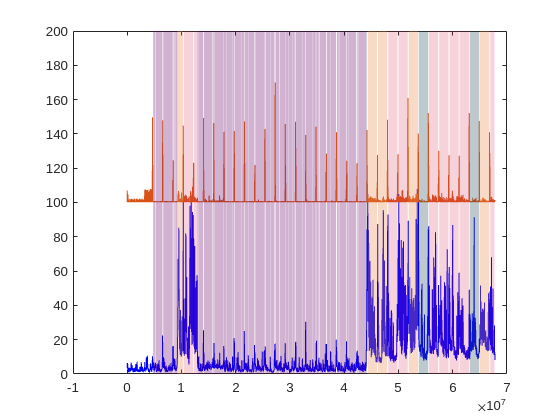

for i = 1:most_events
    try
        startXAl = experiment.conditionVector.aluminumEpochs(i, 1);
        endXAl = experiment.conditionVector.aluminumEpochs(i, 2);
        fill([startXAl, endXAl, endXAl, startXAl], [0, 0, maxY, maxY],'r','FaceColor',colorBen.aluminum,'FaceAlpha',0.2,'EdgeColor','none');
    end
    try
        startXAt = experiment.conditionVector.mutedEpochs(i, 1);
        endXAt = experiment.conditionVector.mutedEpochs(i, 2);
        fill([startXAt, endXAt, endXAt, startXAt], [0, 0, maxY, maxY],'b','FaceColor',colorBen.muted, 'FaceAlpha', 0.3, 'EdgeColor', 'none');
    end
    try
        startXNo = experiment.conditionVector.nonEpochs(i, 1);
        endXNo = experiment.conditionVector.nonEpochs(i, 2);
        fill([startXNo, endXNo, endXNo, startXNo], [0, 0, maxY, maxY],'y','FaceColor',colorBen.non, 'FaceAlpha', 0.3, 'EdgeColor', 'none');

    end
    try
        startXNW = experiment.conditionVector.noWhiskingEpochs(i, 1);
        endXNW = experiment.conditionVector.noWhiskingEpochs(i, 2);
        fill([startXNW, endXNW, endXNW, startXNW], [0, 0, maxY, maxY],'y','FaceColor',colorBen.purple, 'FaceAlpha', 0.3, 'EdgeColor', 'none');

    end
end

% extract FR across conditions for the table
FR_aluminum = experiment.Units.perCondition.aluminum.FR

FR_aluminum =    16.6694
    0.8131
    1.7773
   17.9588
    0.6970
    1.0455
    5.1112
    3.3106
    8.9910
   24.6033


FR_attenuated = experiment.Units.perCondition.muted.FR

FR_attenuated =    15.8667
    0.5300
    1.0716
   19.3696
    1.4173
    1.1292
    5.2543
    2.8691
   10.7046
   25.5803


FR_noObject = experiment.Units.perCondition.non.FR

FR_noObject =    16.5827
    1.3699
    0.9958
   18.0907
    0.8576
    0.6331
    6.9013
    1.5886
    6.4638
   20.3297


FR_NoWhisking = experiment.Units.perCondition.noWhisking.FR

FR_NoWhisking =    14.8461
    2.1400
    0.9665
   15.7095
    0.7531
    1.0343
    1.6373
    0.3969
    3.8966
   20.0971


[AluminumSDF,AluminumBinnedFR,AluminumSTD,aluminumSamples] = getSDFs(experiment.conditionVector.aluminumEpochs,experiment.Units.perCondition.aluminum.times,20)

AluminumSDF = 35×1 cell array
    {86090×1 double}
    {86090×1 double}
    {86090×1 double}
    {86090×1 double}
    {86090×1 double}
    {86090×1 double}
    {86090×1 double}
    {86090×1 double}
    {86090×1 double}
    {86090×1 double}
    {86090×1 double}
    {86090×1 double}
    {86090×1 double}
    {86090×1 double}
    {86090×1 double}
    {86090×1 double}


AluminumBinnedFR = 35×1 cell array
    {86090×1 double}
    {86090×1 double}
    {86090×1 double}
    {86090×1 double}
    {86090×1 double}
    {86090×1 double}
    {86090×1 double}
    {86090×1 double}
    {86090×1 double}
    {86090×1 double}
    {86090×1 double}
    {86090×1 double}
    {86090×1 double}
    {86090×1 double}
    {86090×1 double}
    {86090×1 double}


AluminumSTD =   128.0271
   28.5035
   42.1197
  132.7994
   26.3907
   32.3162
   71.3083
   57.4419
   94.3921
  154.9102


[AttenuatedSDF,AttenuatedBinnedFR,AttenuatedSTD,attenuatedSamples] = getSDFs(experiment.conditionVector.mutedEpochs,experiment.Units.perCondition.muted.times,20)

AttenuatedSDF = 35×1 cell array
    {86790×1 double}
    {86790×1 double}
    {86790×1 double}
    {86790×1 double}
    {86790×1 double}
    {86790×1 double}
    {86790×1 double}
    {86790×1 double}
    {86790×1 double}
    {86790×1 double}
    {86790×1 double}
    {86790×1 double}
    {86790×1 double}
    {86790×1 double}
    {86790×1 double}
    {86790×1 double}


AttenuatedBinnedFR = 35×1 cell array
    {86790×1 double}
    {86790×1 double}
    {86790×1 double}
    {86790×1 double}
    {86790×1 double}
    {86790×1 double}
    {86790×1 double}
    {86790×1 double}
    {86790×1 double}
    {86790×1 double}
    {86790×1 double}
    {86790×1 double}
    {86790×1 double}
    {86790×1 double}
    {86790×1 double}
    {86790×1 double}


AttenuatedSTD =   124.9573
   23.0161
   32.7172
  137.8175
   37.6194
   33.5842
   72.2947
   53.4864
  102.9055
  157.8765


[NoObjectSDF,NoObjectBinnedFR,noObjectSTD,NoObjectSamples] = getSDFs(experiment.conditionVector.nonEpochs,experiment.Units.perCondition.non.times,20)

NoObjectSDF = 35×1 cell array
    {173742×1 double}
    {173742×1 double}
    {173742×1 double}
    {173742×1 double}
    {173742×1 double}
    {173742×1 double}
    {173742×1 double}
    {173742×1 double}
    {173742×1 double}
    {173742×1 double}
    {173742×1 double}
    {173742×1 double}
    {173742×1 double}
    {173742×1 double}
    {173742×1 double}
    {173742×1 double}


NoObjectBinnedFR = 35×1 cell array
    {173742×1 double}
    {173742×1 double}
    {173742×1 double}
    {173742×1 double}
    {173742×1 double}
    {173742×1 double}
    {173742×1 double}
    {173742×1 double}
    {173742×1 double}
    {173742×1 double}
    {173742×1 double}
    {173742×1 double}
    {173742×1 double}
    {173742×1 double}
    {173742×1 double}
    {173742×1 double}


noObjectSTD =   127.6996
   36.9862
   31.5396
  133.2775
   29.2722
   25.1540
   82.7856
   39.8252
   80.1365
  141.1235


[NoWhiskingSDF,NoWhiskingBinnedFR,NoWhiskingSTD,NoWhiskingSamples] = getSDFs(experiment.conditionVector.noWhiskingEpochs,experiment.Units.perCondition.noWhisking.times,20)

NoWhiskingSDF = 35×1 cell array
    {1106122×1 double}
    {1106122×1 double}
    {1106122×1 double}
    {1106122×1 double}
    {1106122×1 double}
    {1106122×1 double}
    {1106122×1 double}
    {1106122×1 double}
    {1106122×1 double}
    {1106122×1 double}
    {1106122×1 double}
    {1106122×1 double}
    {1106122×1 double}
    {1106122×1 double}
    {1106122×1 double}
    {1106122×1 double}


NoWhiskingBinnedFR = 35×1 cell array
    {1106122×1 double}
    {1106122×1 double}
    {1106122×1 double}
    {1106122×1 double}
    {1106122×1 double}
    {1106122×1 double}
    {1106122×1 double}
    {1106122×1 double}
    {1106122×1 double}
    {1106122×1 double}
    {1106122×1 double}
    {1106122×1 double}
    {1106122×1 double}
    {1106122×1 double}
    {1106122×1 double}
    {1106122×1 double}


NoWhiskingSTD =   120.9346
   46.2096
   31.0726
  124.3470
   27.4320
   32.1430
   40.4298
   19.9180
   62.3002
  140.3299


% Create a reference table for the units 
unitID = [experiment.Units.good.id;experiment.Units.mua.id]

unitID =    103
   115
   131
   142
   166
   169
   248
   299
   302
    50


unitType = categorical([repmat("good",length(experiment.Units.good.id),1);repmat("mua",length(experiment.Units.mua.id),1)])

unitType = 35×1 categorical array
     good 
     good 
     good 
     good 
     good 
     good 
     good 
     good 
     good 
     mua 
     mua 
     mua 
     mua 
     mua 
     mua 
     mua 
     mua 
     mua 
     mua 
     mua 
     mua 
     mua 
     mua 
     mua 
     mua 
     mua 
     mua 
     mua 
     mua 
     mua 


Session = repmat({experiment.experiment_ID},length(unitID),1)

Session = 35×1 cell array
    {'FVB108_986'}
    {'FVB108_986'}
    {'FVB108_986'}
    {'FVB108_986'}
    {'FVB108_986'}
    {'FVB108_986'}
    {'FVB108_986'}
    {'FVB108_986'}
    {'FVB108_986'}
    {'FVB108_986'}
    {'FVB108_986'}
    {'FVB108_986'}
    {'FVB108_986'}
    {'FVB108_986'}
    {'FVB108_986'}
    {'FVB108_986'}
    {'FVB108_986'}
    {'FVB108_986'}
    {'FVB108_986'}
    {'FVB108_986'}
    {'FVB108_986'}
    {'FVB108_986'}
    {'FVB108_986'}
    {'FVB108_986'}
    {'FVB108_986'}
    {'FVB108_986'}
    {'FVB108_986'}
    {'FVB108_986'}
    {'FVB108_986'}
    {'FVB108_986'}


referance_table = table(unitID,unitType,Session,FR_aluminum,FR_attenuated,FR_noObject,FR_NoWhisking ...
    ,AluminumSDF,AttenuatedSDF,NoObjectSDF,NoWhiskingSDF,AluminumBinnedFR,AttenuatedBinnedFR, ...
    NoObjectBinnedFR,NoWhiskingBinnedFR,AluminumSTD,AttenuatedSTD,noObjectSTD,NoWhiskingSTD)

referance_table = 35×19 table
    unitID    unitType       Session        FR_aluminum    FR_attenuated    FR_noObject    FR_NoWhisking      AluminumSDF        AttenuatedSDF         NoObjectSDF         NoWhiskingSDF       AluminumBinnedFR    AttenuatedBinnedFR    NoObjectBinnedFR     NoWhiskingBinnedFR    AluminumSTD    AttenuatedSTD    noObjectSTD    NoWhiskingSTD
    ______    ________    ______________    ___________    _____________    ___________    _____________    ________________    ________________    _

filename = [experiment.experiment_ID,'.mat']

filename = 'FVB108_986.mat'


tblFileName = ['condUnits_',filename]

tblFileName = 'condUnits_FVB108_986.mat'

% save(filename,'experiment','-v7.3')
% save(tblFileName,'referance_table','adjustedSamples','conditionVector')


% aluminumSamples = getAdjustedSamples(experiment.conditionVector.aluminumEpochs,30);
% attenuatedSamples = getAdjustedSamples(experiment.conditionVector.mutedEpochs,30);
% NoObjectSamples = getAdjustedSamples(experiment.conditionVector.nonEpochs,30);
% NoWhiskingSamples = getAdjustedSamples(experiment.conditionVector.noWhiskingEpochs,30);

adjustedSamples.Aluminum = aluminumSamples;
adjustedSamples.Attenuated = attenuatedSamples;
adjustedSamples.noObject = NoObjectSamples;
adjustedSamples.NoWhisking = NoWhiskingSamples;

conditionVector = experiment.conditionVector

conditionVector = struct with fields:
      aluminumEpochs: [8×2 int64]
         mutedEpochs: [9×2 int64]
           nonEpochs: [10×2 int64]
    noWhiskingEpochs: [90×2 int64]
            aluminum: [4779576 4779577 4779578 4779579 4779580 4779581 4779582 4779583 4779584 4779585 4779586 4779587 4779588 4779589 4779590 4779591 4779592 4779593 4779594 4779595 4779596 4779597 4779598 4779599 4779600 4779601 4779602 4779603 … ]
               muted: [14198714 14198715 14198716 14198717 14198718 14198719 14198720 14198721 14198722 14198723 14198724 14198725 14198726 14198727 14198728 14198729 14198730 14198731 14198732 14198733 14198734 14198735 14198736 14198737 14198738 … ]
                 non: [10431589 10431590 10431591 10431592 10431593 10431594 10431595 10431596 10431597 10431598 10431599 10431600 10431601 10431602 10431603 10431604 10431605 10431606 10431607 10431608 10431609 10431610 10431611 10431612 10431613 … ]
          noWhisking: [4774911 4774912 4774913 4774914 4774915 477491

alignedTimes = experiment.timeStamp

alignedTimes = struct with fields:
           ephys: [3574 19887127 51798443]
         avisoft: [155182 165870808 431829382]
      alignedAvi: [NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN … ]
    alignedEphys: [NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN … ]


save(filename,'experiment','-v7.3')

save(tblFileName,'referance_table','adjustedSamples','conditionVector','alignedTimes','-v7.3',"-append")      

function [SDFs,unitVecBinned,unitSTD] = getSDFs(conditionEpochs,unitsStruct,sigma)
% use condition spike times and condition epochs to generate a SDF for all
% units. sigma should be in units of ms.
    SDFs = {};
    edges = [-3*sigma:1:3*sigma];
    kernel = normpdf(edges,0,sigma)*1000;
    binSize = 30;
    unitVecBinned = {};
    unitSTD = [];
    for un = 1:length(unitsStruct)
        unitVbinned = [];
        SDFV = [];
        unitTrain = unitsStruct{un};
        for ep = 1:size(conditionEpochs)
            epTimes = [conditionEpochs(ep,1):conditionEpochs(ep,2)];
            unitTemp = ismember(epTimes,unitTrain);
            padding = mod(length(unitTemp),binSize);
            if padding ~= 0
                padding = binSize-padding;
            end
            paddedSpiketrain = [unitTemp,zeros(1,padding)];
            binnedSpikeTrain = sum(reshape(paddedSpiketrain,binSize,[]));
            unitVbinned = [unitVbinned,binnedSpikeTrain];
            SDFtemp = conv(binnedSpikeTrain,kernel,'same');
            SDFV = [SDFV,SDFtemp];
        end
        SDFs{un,1} = SDFV';
        unitVecBinned{un,1} = unitVbinned';
        unitSTD(un) = std(unitVbinned*1000);
    end
    unitSTD = unitSTD';

end
% function adjustedSamples = getAdjustedSamples(conditionEpochs, binSize)
% % Use condition epochs to generate adjusted samples.
% 
%     adjustedSamples = []; % Initialize as an empty array
% 
%     for ep = 1:size(conditionEpochs, 1)
%         epStart = conditionEpochs(ep, 1);
%         epEnd = conditionEpochs(ep, 2);
% 
%         % Calculate the number of samples in this epoch
%         numSamples = epEnd - epStart + 1;
% 
%         % Calculate the necessary padding
%         padding = mod(numSamples, binSize);
%         if padding ~= 0
%             padding = binSize - padding;
%         end
% 
%         % Calculate the length of binnedSpikeTrain
%         binnedLength = (numSamples + padding) / binSize;
% 
%         % Calculate the adjusted sample indices for each epoch
%         % The length of adjustedSampleEpoch should match the length of binnedSpikeTrain
%         adjustedSampleEpoch = linspace(double(epStart), double(epEnd + padding), binnedLength);
% 
%         % Concatenate to form a continuous vector
%         adjustedSamples = [adjustedSamples, adjustedSampleEpoch];
%     end
% end

